## **Load data **

% load data 1 and data 2
data_load = load("../EEG_data/FIBROP001_DD1_BL_clean.mat");
data_before_car = data_load.data_clean;
data_load_2 = load("../EEG_data/FIBROP001_DD2_90_clean.mat");
data_before_car_2 = data_load_2.data_clean;

% % (need more data from more participants --> later implement for loop)
% % load data 1 and data 2 for participant 2
% data_load_3 = load("EEG_data/FIBROP002_DD1_150_clean.mat");
% data_before_car_3 = data_load_3.data_clean;
% data_load_4 = load("EEG_data/FIBROP002_DD2_150_clean.mat");
% data_before_car_4 = data_load_4.data_clean;

% implement CAR re-referencing
cfg = [];
cfg.channel = 'all'; % this is the default
cfg.reref = 'yes';
cfg.refmethod = 'avg';
cfg.refchannel = 'all';
data = ft_preprocessing(cfg, data_before_car);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 56 MB


data_2 = ft_preprocessing(cfg, data_before_car_2);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 63 MB
preprocessing
preprocessing trial 86 from 86

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 74 MB



% disp(det(residual_variance));

% Preprocessed data in FieldTrip format
% data = your_preprocessed_data;

% Define range of model orders to test
max_order = 20;
AIC_values = zeros(1, max_order);
BIC_values = zeros(1, max_order);

trial_lengths = cellfun(@(x) size(x, 2), data.trial); 
n_samples = sum(trial_lengths); % because biosig will concatenate the trials % size(data.trial{1}, 2); % Assuming consistent trial length
% N = sum(cellfun(@(x) size(x, 2), data.trial)); % Total number of time points

for order = 1:max_order
    % Fit MVAR model
    cfg = [];
    cfg.order = order;
    cfg.keeptrial = 'yes';
    cfg.method = 'biosig'; % Or 'biosig', or another supported toolbox
    mvar = ft_mvaranalysis(cfg, data);

    num_channels = size(mvar.noisecov, 1); % Number of channels (size of noisecov matrix)
    % ridge regularization to avoid negative determinant (?)
    epsilon = 1e-6; 
    residual_variance = mvar.noisecov + epsilon * eye(size(mvar.noisecov)); % noise covariance matrix

    % Extract log-likelihood and number of parameters
    log_noisecov = log(det(residual_variance));
    log_likelihood = -0.5 * n_samples * (num_channels * log(2 * pi) + log_noisecov + num_channels); 
    num_params = order * num_channels^2;

    % Calculate AIC and BIC
    AIC_values(order) = -2 * log_likelihood + 2 * num_params;
    BIC_values(order) = -2 * log_likelihood + num_params * log(n_samples);
end

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 65 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 8 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 80 MB

the call to "ft_mvaranalysis" took 2 seconds and required the additional allocation of an estimated 520 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 637 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 18 MB

the call to "ft_mvaranalysis" took 2 seconds and required the additional allocation of an estimated 638 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 635 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 639 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 639 MB

the call to "ft_mvaranalysis" took 3 seconds and required the additional allocation of an estimated 635 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 567 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 567 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 567 MB

the call to "ft_mvaranalysis" took 4 seconds and required the additional allocation of an estimated 568 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 567 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 570 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 568 MB

the call to "ft_mvaranalysis" took 4 seconds and required the additional allocation of an estimated 569 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 569 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 642 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 641 MB

the call to "ft_mvaranalysis" took 5 seconds and required the additional allocation of an estimated 569 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 568 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 570 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 570 MB

the call to "ft_mvaranalysis" took 6 seconds and required the additional allocation of an estimated 571 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 572 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 575 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 573 MB

the call to "ft_mvaranalysis" took 6 seconds and required the additional allocation of an estimated 574 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 572 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 577 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 575 MB

the call to "ft_mvaranalysis" took 7 seconds and required the additional allocation of an estimated 572 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 570 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 15 MB

the call to "ft_mvaranalysis" took 9 seconds and required the additional allocation of an estimated 572 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 573 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 3 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 17 MB

the call to "ft_mvaranalysis" took 10 seconds and required the additional allocation of an estimated 573 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 574 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 648 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 648 MB

the call to "ft_mvaranalysis" took 10 seconds and required the additional allocation of an estimated 574 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 580 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 580 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 580 MB

the call to "ft_mvaranalysis" took 9 seconds and required the additional allocation of an estimated 578 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 577 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 579 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 579 MB

the call to "ft_mvaranalysis" took 10 seconds and required the additional allocation of an estimated 577 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 576 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 579 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 577 MB

the call to "ft_mvaranalysis" took 11 seconds and required the additional allocation of an estimated 576 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 573 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 647 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 575 MB

the call to "ft_mvaranalysis" took 12 seconds and required the additional allocation of an estimated 578 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 17 MB

the call to "ft_mvaranalysis" took 12 seconds and required the additional allocation of an estimated 579 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 577 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 580 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 578 MB

the call to "ft_mvaranalysis" took 12 seconds and required the additional allocation of an estimated 580 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 581 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 581 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 581 MB

the call to "ft_mvaranalysis" took 15 seconds and required the additional allocation of an estimated 581 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 581 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 583 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 583 MB

the call to "ft_mvaranalysis" took 16 seconds and required the additional allocation of an estimated 581 MB


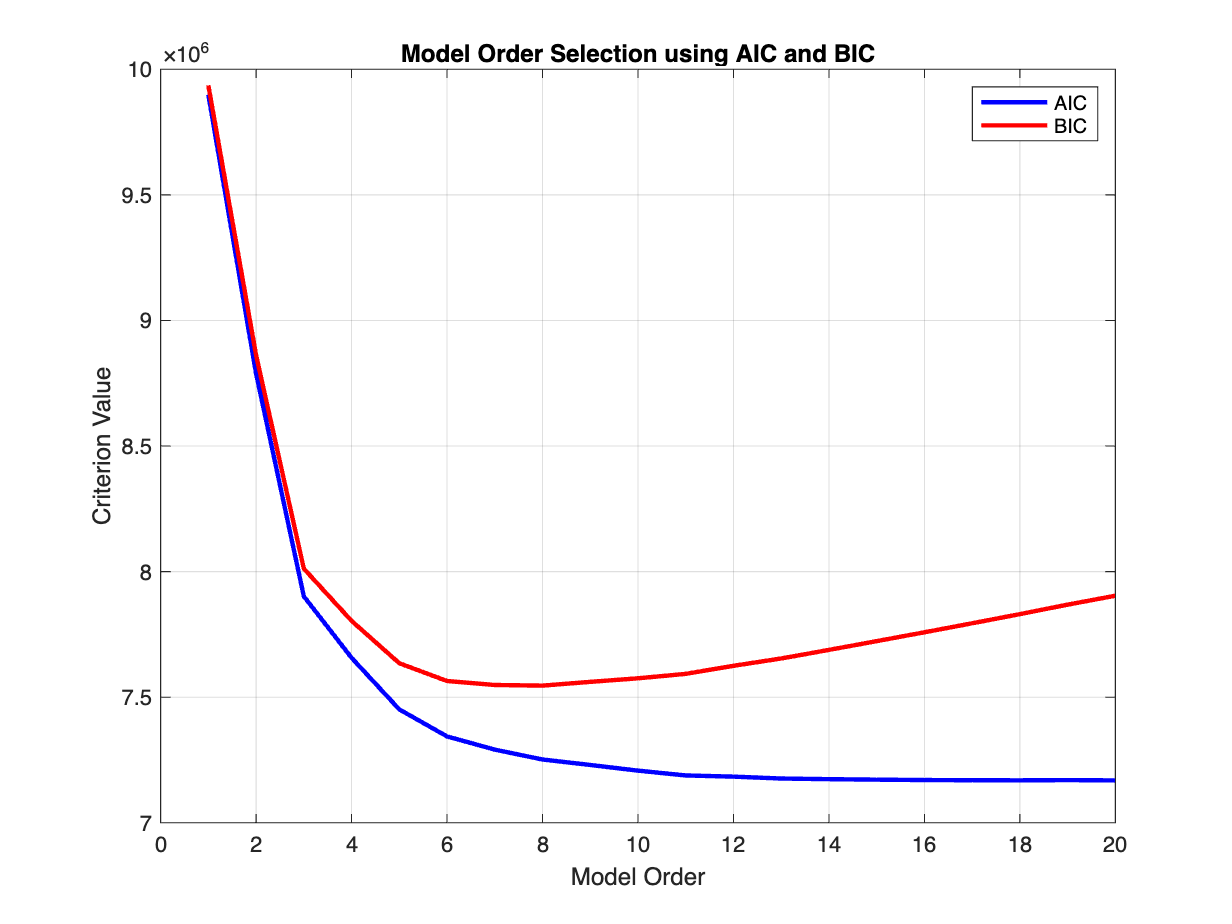

% Find the optimal order
[~, optimal_order_AIC] = min(AIC_values);
[~, optimal_order_BIC] = min(BIC_values);

% Plot AIC and BIC
figure;
plot(1:max_order, AIC_values, 'b-', 'LineWidth', 2); hold on;
plot(1:max_order, BIC_values, 'r-', 'LineWidth', 2);
legend('AIC', 'BIC');
xlabel('Model Order');
ylabel('Criterion Value');
title('Model Order Selection using AIC and BIC');
grid on;


disp(['Optimal Order (AIC): ', num2str(optimal_order_AIC)]);

Optimal Order (AIC): 20


% disp(test1);
disp(['Optimal Order (BIC): ', num2str(optimal_order_BIC)]);

Optimal Order (BIC): 8


% % Example: Selecting optimal order using ARFIT toolbox
% [~,~,order] = arfit(data.trial, 1, 20); % Search for order between 1 and 20
% disp(['Optimal order: ', num2str(order)]);

% cov_matrix = cov(data_resampled.trial{1}');
% disp(eig(cov_matrix)); % Check eigenvalues

% % Inspect trial data passed to ft_mvaranalysis
% disp(size(data_resampled.trial{1})); % Should show [num_channels, num_samples]
% disp(var(data_resampled.trial{1}, 0, 2)); % Variance across channels

cfg = [];
cfg.order = 8; % Define model order
cfg.toolbox = 'biosig'; % % Use the biosig toolbox (FieldTrip default)

mdata = ft_mvaranalysis(cfg, data);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 90 MB

the call to "ft_mvaranalysis" took 7 seconds and required the additional allocation of an estimated 502 MB


mdata_2 = ft_mvaranalysis(cfg, data_2);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
preprocessing
preprocessing trial 86 from 86

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 109 MB

the call to "ft_mvaranalysis" took 8 seconds and required the additional allocation of an estimated 737 MB


int_chan_labels = cellstr(intersect(string(data.label), string(data_2.label)));

cfg        = [];
cfg.method = 'mvar';
cfg.foilim    = [8 13];
% cfg.channel   = int_chan_labels;

mfreq      = ft_freqanalysis(cfg, mdata);

the input is mvar data
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
computing MAR-model based TFR
processing timewindow 1 from 1

the call to "ft_freqanalysis_mvar" took 0 seconds and required the additional allocation of an estimated 3 MB


mfreq_2      = ft_freqanalysis(cfg, mdata_2);

the input is mvar data
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 8 MB
computing MAR-model based TFR
processing timewindow 1 from 1

the call to "ft_freqanalysis_mvar" took 0 seconds and required the additional allocation of an estimated 40 MB



% %% compute granger causality connectivity
% cfg           = [];
% cfg.method    = 'granger';
% cfg.granger.sfmethod = 'bivariate';
% granger      = ft_connectivityanalysis(cfg, mvar_data);

cfg           = [];
cfg.method    = 'granger';
granger       = ft_connectivityanalysis(cfg, mfreq);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 15 MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated 15 MB


granger_2       = ft_connectivityanalysis(cfg, mfreq_2);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 27 MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated 27 MB


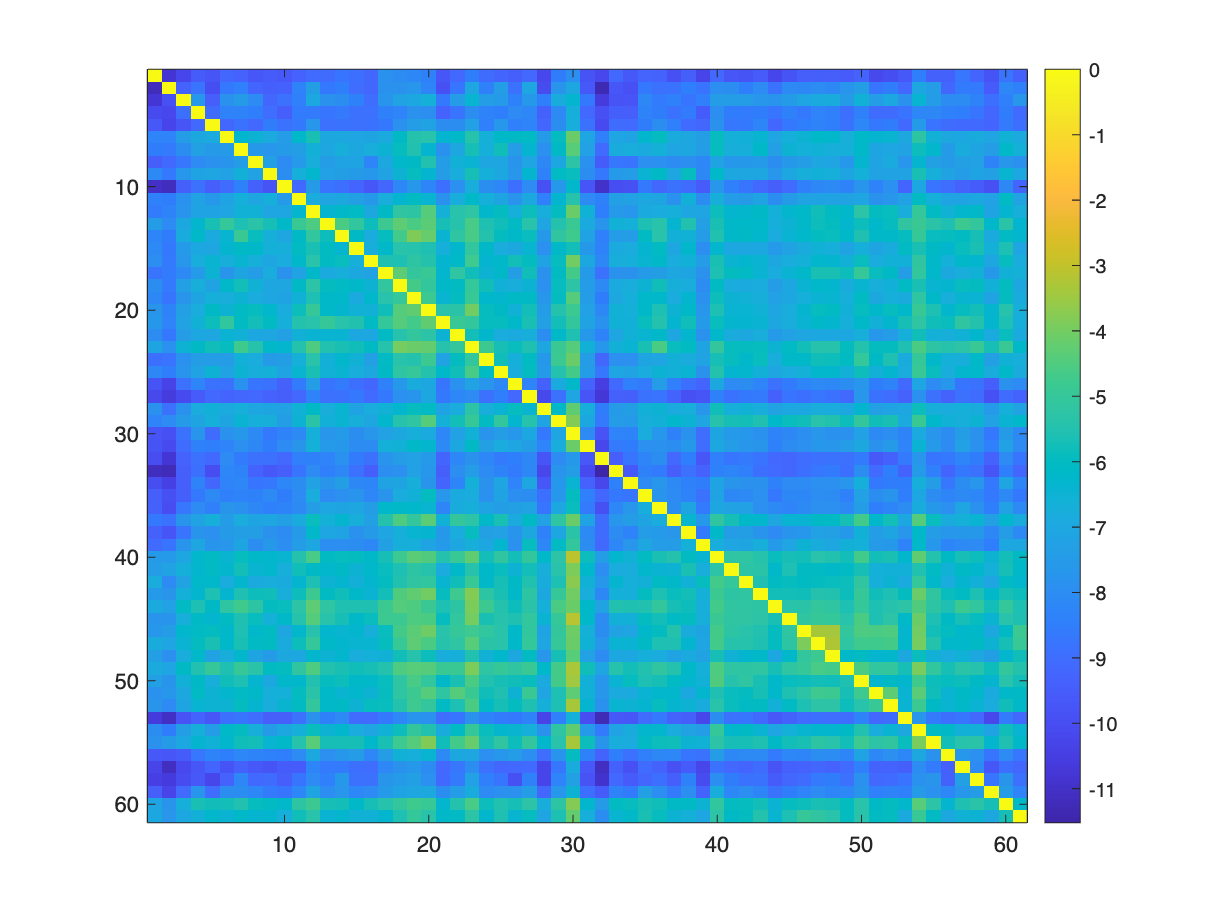

conn_mat = mean(granger.grangerspctrm, 3);
figure;imagesc(conn_mat);
cbh = colorbar();

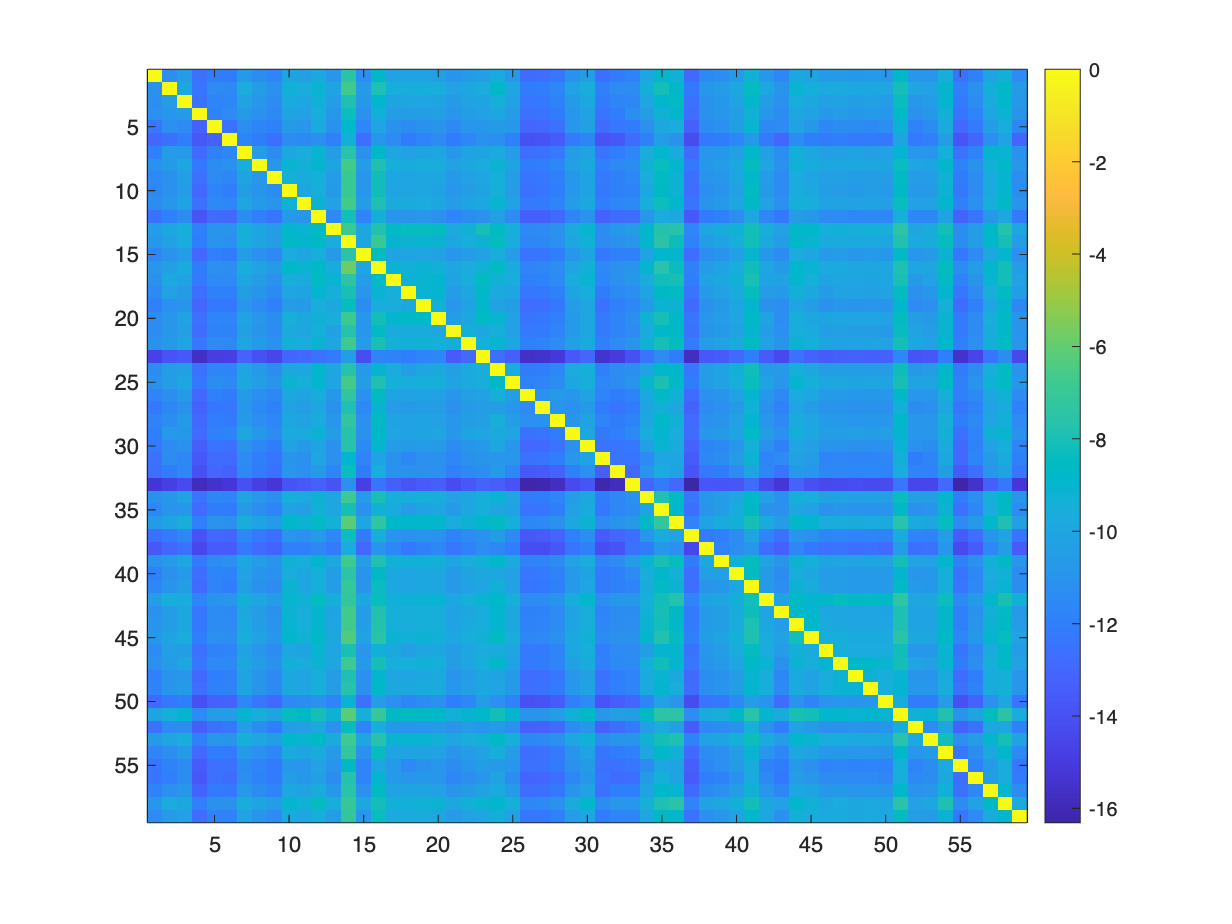

conn_mat_2 = mean(granger_2.grangerspctrm, 3);
figure;imagesc(conn_mat_2);
cbh = colorbar();

% diff_conn_mat = conn_mat_2 - conn_mat;

Arrays have incompatible sizes for this operation.

Related documentation

% figure;imagesc(diff_conn_mat);
% cbh = colorbar();


labels_mask = ~ismember(granger.label, int_chan_labels);
labels_mask_2 = ~ismember(granger_2.label, int_chan_labels);

% labels_mask_mat = repmat(labels_mask, 1, size(labels_mask, 1));
% labels_mask_mat = and(labels_mask_mat, labels_mask_mat.');
% labels_mask_mat_2 = repmat(labels_mask_2, 1, size(labels_mask_2, 1));
% labels_mask_mat_2 = and(labels_mask_mat_2, labels_mask_mat_2.');

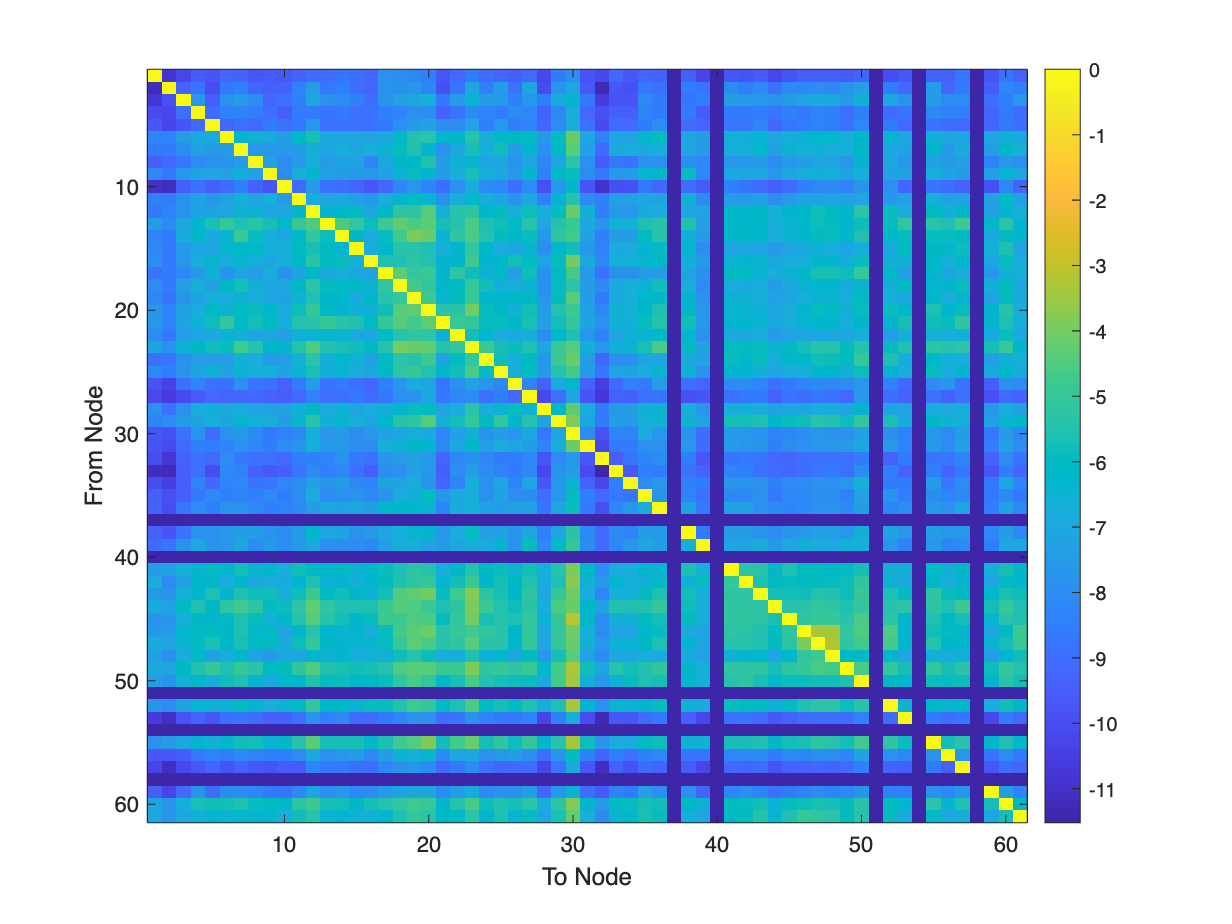

des_conn_mat = mean(granger.grangerspctrm, 3);
% Apply the mask to rows
des_conn_mat(labels_mask, :) = NaN;
% Apply the mask to columns
des_conn_mat(:, labels_mask) = NaN;

% conn_mat = conn_mat(labels_mask_mat);
% [I, J] = find(labels_mask_mat);
% des_conn_mat(I)   = conn_mat(sub2ind(size(conn_mat), I, J));
% des_conn_mat      = des_conn_mat(:);
figure;imagesc(des_conn_mat);
xlabel('To Node');
ylabel('From Node');
cbh = colorbar();

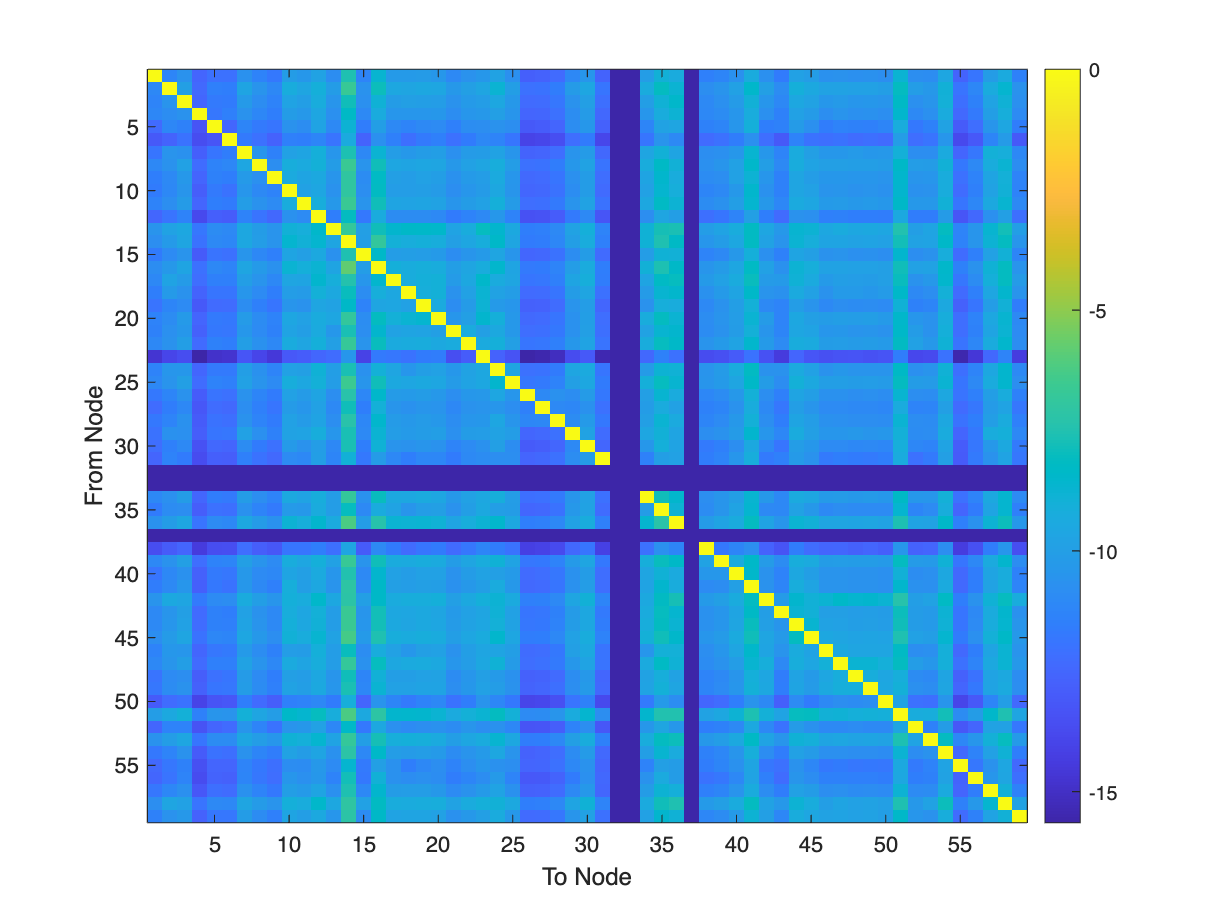

des_conn_mat_2 = mean(granger_2.grangerspctrm, 3);
% Apply the mask to rows
des_conn_mat_2(labels_mask_2, :) = NaN;
% Apply the mask to columns
des_conn_mat_2(:, labels_mask_2) = NaN;

figure;imagesc(des_conn_mat_2);
xlabel('To Node');
ylabel('From Node');
cbh = colorbar();

% diff_conn_mat = des_conn_mat_2 - des_conn_mat;
% figure;imagesc(diff_conn_mat);

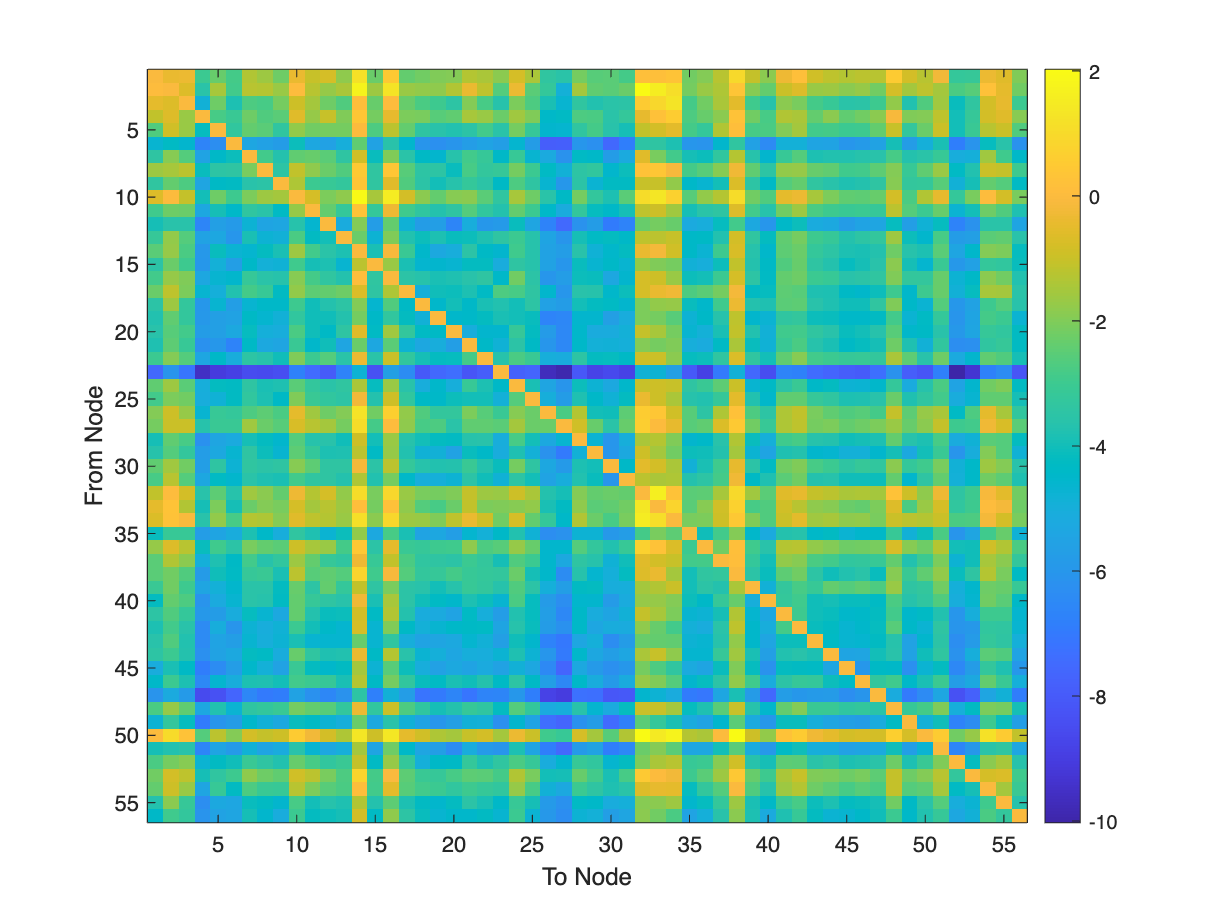

% cbh = colorbar();

% Create a logical mask for non-NaN values
nonNaNMask = ~labels_mask;
% Extract only the non-NaN values
conn_mat = des_conn_mat(nonNaNMask, nonNaNMask);

% Create a logical mask for non-NaN values
nonNaNMask = ~labels_mask_2;
% Extract only the non-NaN values
conn_mat_2 = des_conn_mat_2(nonNaNMask, nonNaNMask);

diff_conn_mat = conn_mat_2 - conn_mat;
figure;imagesc(diff_conn_mat);
xlabel('To Node');
ylabel('From Node');
cbh = colorbar();